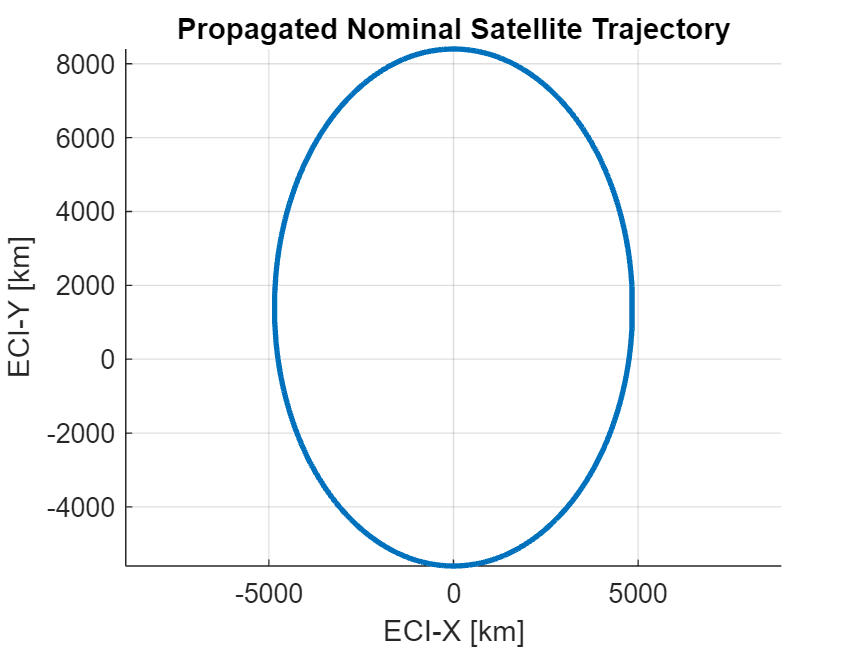

%Project Step 0a: - Defining Initial Values and Givens
    %Loading measurements...
    load("Project-Measurements-Easy.mat")

    %Defining location of sites - formatted [lat,long] with row index corresponding to site number...
    SiteCoordinates = [35.297,-116.914;40.4311,-4.248;-35.4023,148.9813];

    %Defining given frame values...
    w_e_n = 7.292115*10^-5; %rad/s - Rotation Rate of Earth.
    gamma_0 = 0; %deg - Local Sidereal Time.
    mu = 398600.4418; %km^3/s^2 - Earth Gravitational Parameter.
    r_earth = 6378.137; %km - Radius of Earth.

    %Defining nominal orbit parameters...
    a_nom = 7000; %km - Semi-Major Axis of Nominal Orbit.
    e_nom = 0.2; %dimless - Eccentricity of the Nominal Orbit
    i_nom = 45; %deg - Inclination of the Nominal Orbit
    w_nom = 0; %deg - Argument of Periapsis of the Nominal Orbit
    Omega_nom = 270; %deg - Longitude of Ascending Node of the Nominal Orbit
    TA_nom = 78.75; %deg - True Anomaly of the Nominal Orbit at T=0
    OE_Nom = [a_nom,e_nom,i_nom,w_nom,Omega_nom,TA_nom]; %mixed - Array of Nominal Orbital Elements

%Project Step 0b: - Inspecting the Trajectory of the Nominal Orbit
    %Convert OEs to Cartesian ECI State Vector...
    delta_t = 2*pi*sqrt(a_nom^3/mu); %Propagate nominal trajectory for one orbit.
    t_step = 0.1;
    [r_nom,v_nom] = OE2Cart(OE_Nom,mu);

    %Propagate and Display Reference Orbit...
    [t_prop_nom,soln_prop_nom] = propOrbit(r_nom,v_nom,delta_t,t_step);
    figure()
    hold on %Will overlay kalman-filter orbital estimates onto this later.
    plot3(soln_prop_nom(:,1),soln_prop_nom(:,2),soln_prop_nom(:,3),LineWidth=2)
    axis equal
    grid on
    xlabel("ECI-X [km]")
    ylabel("ECI-Y [km]")
    zlabel("ECI-Z [km]")
    title("Propagated Nominal Satellite Trajectory")


%Project Step 0c: - Converting the Location of Ground Stations (Tropocentric to ECI)
    %Define ECI Position Array of Active Ground Station...
    R_site = zeros(size(data,1),3); %Columns are X,Y,Z ECI Coords of Active Site, each row corresponds to the corresponding active time in the data.
    %WIP, Still Need to Implement Code for this here...

%Project Step 1: - Problem Setup
    %a.) Express the non-linear system in continous time SS form.
    delta_t = 0;
    [r,v] = RSite2ECI(0,0,delta_t,gamma_0,w_e_n,r_earth)

r = 1.0e+03 *

    6.3781         0         0


v =          0    0.4651         0


%Project Addendum: Helper Functions

function drdt = propagate_2BP(t,r) %Orbital Dynamics Diff-EQ Function
    mu = 398600.4418; %km^3/s^2 - Earth Gravitational Parameter.
    drdt = zeros(6, 1);
    drdt(1:3) = r(4:6);
    r_mag = norm(r(1:3));
    drdt(4:6) = (-mu / r_mag^3) * r(1:3);
end

function [t,soln] = propOrbit(r,v,delta_t,t_step) %Propagates ECI Coordinates using Numerical Tools
    inputs_OBT = [r;v];
    t_range = 0:t_step:delta_t;
    tolerance = 10^-13; %Change parameter to change propgator tolerance.
    options = odeset('RelTol',tolerance,'AbsTol',tolerance);
    [t, soln] = ode45(@propagate_2BP, t_range, inputs_OBT, options);
end

function [r,v] = OE2Cart(input,mu) %Converts Orbital Elements to Cartesian Coordinates in ECI Frame
        %Process inputs and convert degrees to radians...
        a = input(1);
        e = input(2);
        i = deg2rad(input(3));
        w = deg2rad(input(4));
        LAN = deg2rad(input(5));
        TA = deg2rad(input(6));

        %Calculate quantities used in conversion...
        p = a*(1-e^2); %Semi Latus Rectum
        r_mag = p/(1+e*cos(TA)); %Magnitude of R
        r_PQW = [r_mag * cos(TA); r_mag * sin(TA); 0]; %Perifocal Position
        v_PQW = sqrt(mu / p) * [-sin(TA); (e + cos(TA)); 0]; %Perifocal Velocity
        
        %Define 3-1-3 Rotation Matrix...
        ROmega = [cos(LAN),  sin(LAN), 0; 
                  -sin(LAN), cos(LAN), 0; 
                  0,         0,        1];
        RInc = [1,  0,          0; 
                0,  cos(i),     sin(i);
                0, -sin(i),     cos(i)];
        RW = [cos(w),  sin(w), 0; 
              -sin(w), cos(w), 0;
              0,       0,      1];
        RotMatrix = (RW * RInc * ROmega)';

        %Execute Transformation...
        r = RotMatrix * r_PQW;
        v = RotMatrix * v_PQW;
end

function [r,v] = RSite2ECI(lat,long,delta_t,gamma_0,w_e_n,r_earth) %Converts site position to ECI state-vec at a given T past 0.
    gamma = gamma_0 + w_e_n*delta_t;
    ECEF2ECI = transpose([cos(-gamma),  sin(-gamma), 0; 
                          -sin(-gamma), cos(-gamma), 0;
                          0,       0,      1]); %Transposing the ECI2ECEF matrix to invert it.
    ThreeRot = -(90+long); %Expects long and lat in degrees
    OneRot = -(90-lat);
    M3 = [cosd(ThreeRot),  sind(ThreeRot), 0; 
          -sind(ThreeRot), cosd(ThreeRot), 0;
          0,       0,      1];
    M1 =[1,  0,          0; 
         0,  cosd(OneRot),     sind(OneRot);
        0 , -sind(OneRot),     cosd(OneRot)];
    Tropo2ECEF = M3*M1;
    ENU_r = [0,0,r_earth]; %A position of 0,0,r_earth relative to the center of the earth is the site. 
    ECEF_r = Tropo2ECEF*ENU_r';
    r = transpose(ECEF2ECI*ECEF_r);
    VelEQ = w_e_n*r_earth; %Tangential Velocity of the Earth at the Equator.
    VelSite = VelEQ*cosd(lat); %Tangential Velocity of the site. Km/s;
    ENU_v = [VelSite,0,0]; %Earth's rotational velocity is only eastward.
    ECEF_v = Tropo2ECEF*ENU_v';
    v = transpose(ECEF2ECI*ECEF_v);
end